# Modulation Classification with Deep Learning

Modulation identification is an important function for an intelligent receiver. It has numerous applications in cognitive radar, software-defined radio, and efficient spectrum management. To identify both communications and radar waveforms, it’s necessary to classify them by modulation type. For this, meaningful features can be input to a classifier.

While effective, this procedure can require extensive effort and domain knowledge to yield an accurate classification. This exercise will explore a framework to automatically extract time-frequency features from signals. The features will then be used to perform modulation classification with a deep-learning network. 

The trained Convolutional Neural Network (CNN) in this example recognizes 6 modulation types: 

- Binary phase shift keying (BPSK)

- Quadrature phase shift keying (QPSK)

- Gaussian frequency shift keying (GFSK)

- 16-ary quadrature amplitude modulation (16-QAM)

- 64-ary quadrature amplitude modulation (64-QAM)

- 4-ary pulse amplitude modulation (PAM4)

*Copyright 2022 The MathWorks, Inc.*

## Are You in the Correct Directory?

% Run this to check proper configuration 

% Start from a clean workspace
clearvars

if isfolder('2-HelperFiles')
    disp('You are in the correct directory. Please continue.')
    addpath('2-HelperFiles')
   
else  
    error('Please navigate to the proper Directory')
end

## Load Dataset 

To get a feel for the dataset, we will first load the data. We have 200 frames for each channel impaired modulation type. Each frame is 1024 samples long and has a sample rate of 200 kHz. For digital modulation types, 8 samples represent a symbol. The network makes each decision based on single frames rather than on multiple consecutive frames. 

We also split the dataset such that 80% is used for training, 20% is used for testing. We will use training frames during the network training phase test frames to obtain final classification accuracy.

% Load data for Training and Testing 
load('modulationData.mat')

% Observe the dimensions of train and test frames 
sampleFrame= rxTrainFrames{1};
whos

## View Dataset

Next we will plot spectrograms for a sample of frames. 

% Plot spectrogram of example frames
hPlotSpectogram(rxTrainFrames,rxTrainLabels)

## Design a Deep Learning Network Interactively  (Chrome Only)

Using a different browser? Jump to **THIS** section.

The [Deep Network Designer](https://www.mathworks.com/help/deeplearning/ref/deepnetworkdesigner-app.html) (DND) is an app that provides a graphical interface creating and training deep networks. We will perform the entire deep learning workflow in the Deep Network Designer app.

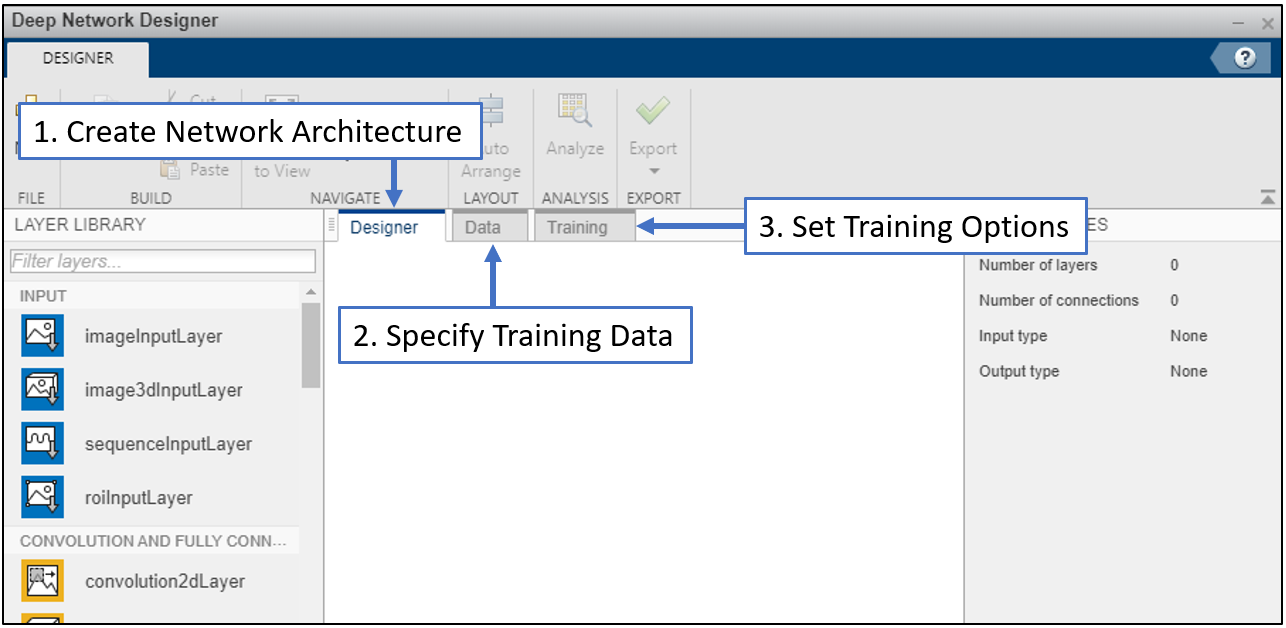

#### Step 1: Create Network Architecture 

We will create the architecture shown below in the "Designer" tab. For your reference, we have partially created the network for you. 

deepNetworkDesigner(hCreatePartialNetwork()) % Only supported in Google Chrome

**To do: Add the three highlighted layers to the network with their respective property values shown in the diagram below.**

For general network design guidance, see [Deep Learning Tips and Tricks](https://www.mathworks.com/help/deeplearning/ug/deep-learning-tips-and-tricks.html). 

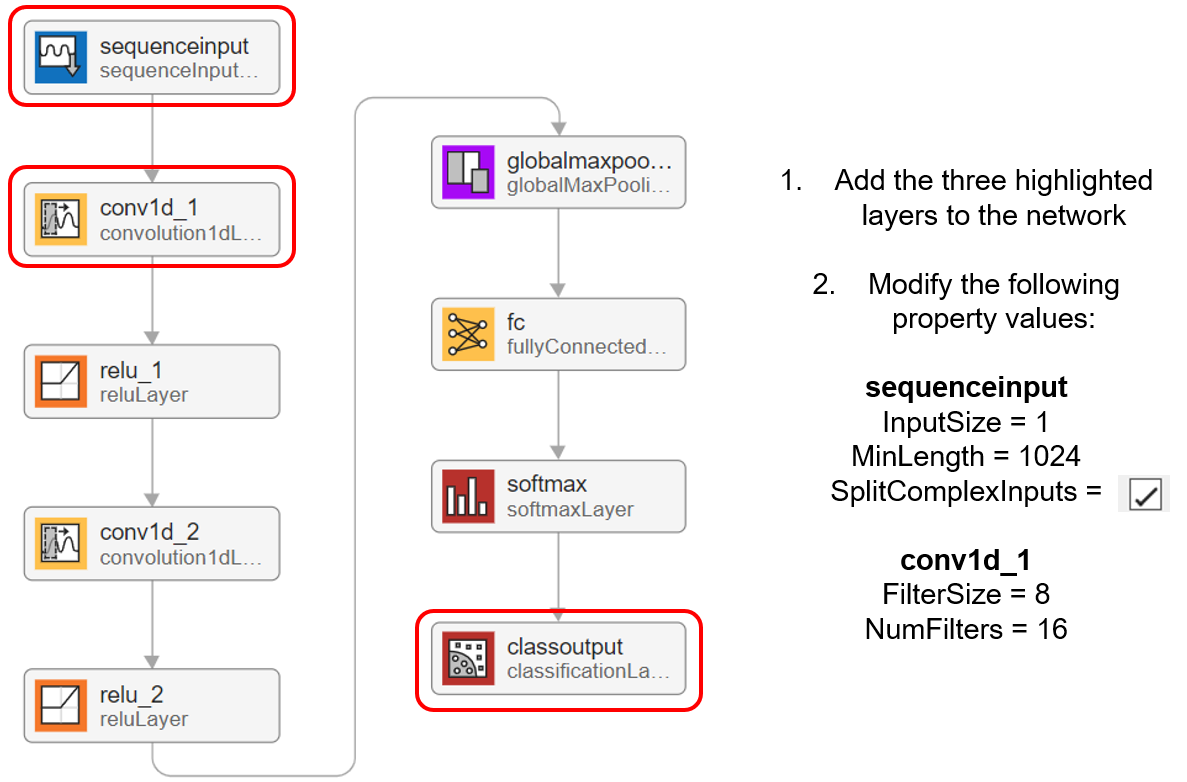

Starting in MATLAB R2022b, we can use the input layer to split the complex values into their real and imaginary parts before the network passes the data to the subsequent layers. When the layer splits complex-valued data, the layer outputs the data in twice as many channels as the input data. To input complex-valued data into a network by splitting it into its real and imaginary parts, set the SplitComplexInputs option of the network input layer to 1 (true).

#### Step 2: Analyze the network for its dataflow and any possible errors

We use the Deep Learning Network Analyzer to visualize and understand the architecture of a network, check that we have defined the architecture correctly, and detect problems before training. 

Select "Analyze", to open the Deep Learning Network Analyzer

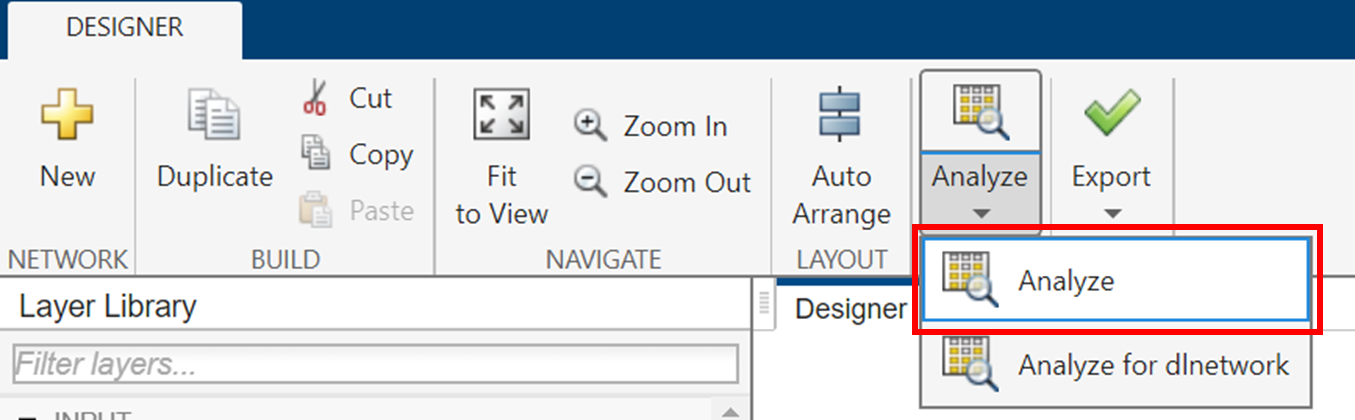

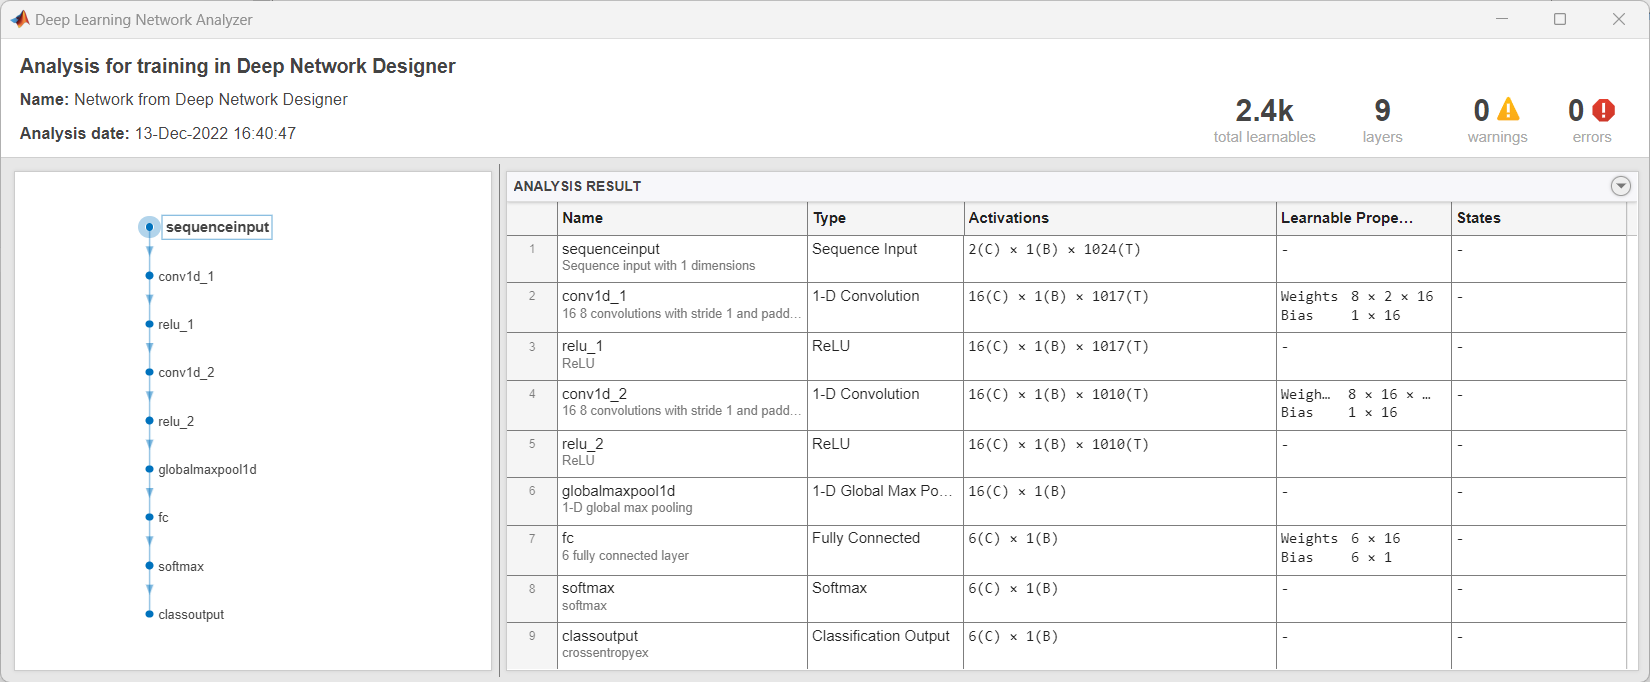

#### Step 3: Export the Network 

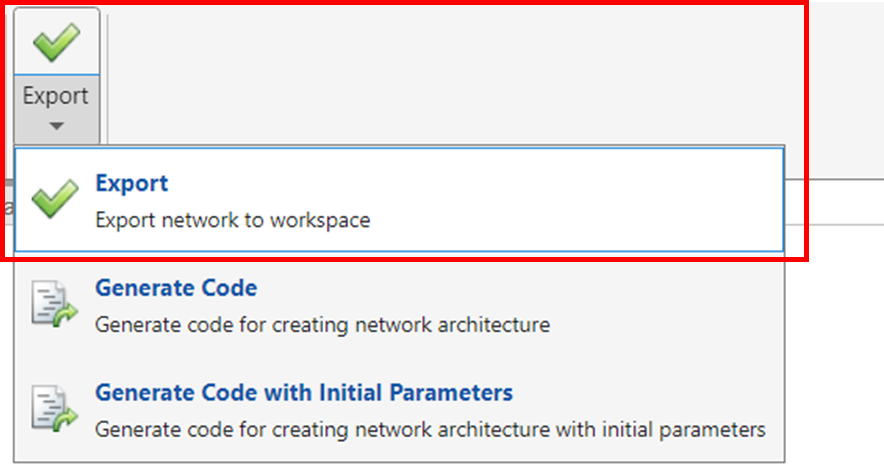

Note the variable name of the exported network. We will be using this network in the rest of this exercise.

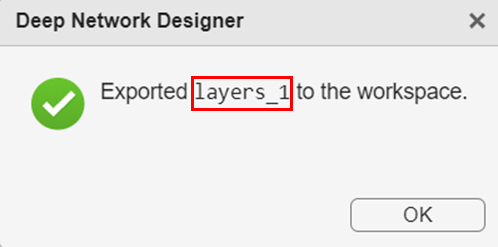

Jump to **THIS** section if you created the network interactively using Deep Network Designer. 

## Design a Deep Learning Network Programmatically (Non-Chrome browsers)

If using a different browser, run the following sections. 

#### **Step 1: Create Network Architecture**

We will now use information regarding our data to create a convolutional neural network. 

**TO DO: Specify Input and Convolutional Filter Size based on Modulation Data **

- Samples per frame (SPF) = 1024 

- Sample per Symbol (SPS) = 8 

% ADD CODE HERE
% spf = 
% sps = 

layers_1 = [
  sequenceInputLayer(1,'SplitComplexInputs',1,'MinLength',spf) 
  convolution1dLayer(sps, 16)
  reluLayer
  convolution1dLayer(sps, 16)
  reluLayer
  globalMaxPooling1dLayer
  fullyConnectedLayer(6)
  softmaxLayer
  classificationLayer ];


#### **Step 2: Analyze the network for its dataflow and any possible errors**

We use the Deep Learning Network Analyzer to visualize and understand the architecture of a network, check that we have defined the architecture correctly, and detect problems before training. 

analyzeNetwork(layers_1)

## **Set Training Options **

[Training options](https://www.mathworks.com/help/deeplearning/ref/trainingoptions.html), AKA hyperparameters, tell our network how to run the training. 

In this section, we will change **Max epochs** which controls how many times we pass our training images through the network during training and **Initial learning rate** which contributes to whether we can minimize loss function of the network optimization algorithm. If the learning rate is too high, the loss function never converges to a minimum and if it is too low, the loss function converges on a local minima and the accuracy will not be as high as it could be.

**TO DO: Set Training Options for the network  **

- `Set maxEpochs equal to 150`

- `Set initialLearnRate equal to 0.01`

% ADD CODE HERE
% maxEpochs = 
% initialLearnRate = 

options = trainingOptions('adam', ...
  'InitialLearnRate',initialLearnRate, ...
  'MaxEpochs',maxEpochs, ...
  'Shuffle','every-epoch', ...
  'Plots','training-progress');

## **Train the Network **

**TO DO: Input the arguments for training our network**

- `Argument_1 = rxTrainFrames`

- `Argument_2 = rxTrainLabels`

- `Argument_3 = variable name for layer architecture `

% Train the network
modPredNetwork = trainNetwork(Argument_1, Argument_2, Argument_3, options); % ADD CODE HERE 

## Evaluate Network Accuracy

We now evaluate the network for all test frames and plot the confusion matrix for the test frames. 

**To Do:** Use the [`classify`](https://www.mathworks.com/help/deeplearning/ref/classify.html) command to classify all frames from the  test dataset

- `Argument_4 = modPredNetwork`

- `Argument_5 = rxTestFrames`

% Test the network accuracy for all frames in the test data
rxTestPred = classify(Argument_4, Argument_5); % ADD CODE HERE

testAccuracy = mean(rxTestPred == rxTestLabels);
disp("Test accuracy: " + testAccuracy*100 + "%")
figure
confusionchart(rxTestLabels, rxTestPred,... 
    "Title","Confusion Matrix for Test Data", ...
    "RowSummary", "row-normalized");

## Further Exploration

It is possible to optimize the hyperparameters parameters, such as number of filters, filter size, or optimize the network structure, such as adding more layers, using different activation layers, etc. to improve the accuracy.

For more information on a more advanced example including data generation with channel impairments, refer to the following documentation example:

[https://www.mathworks.com/help/deeplearning/ug/modulation-classification-with-deep-learning.html](https://www.mathworks.com/help/deeplearning/ug/modulation-classification-with-deep-learning.html)

## **References**

- O'Shea, T. J., J. Corgan, and T. C. Clancy. "Convolutional Radio Modulation Recognition Networks." Preprint, submitted June 10, 2016. [https://arxiv.org/abs/1602.04105](https://arxiv.org/abs/1602.04105)

- O'Shea, T. J., T. Roy, and T. C. Clancy. "Over-the-Air Deep Learning Based Radio Signal Classification." IEEE Journal of Selected Topics in Signal Processing. Vol. 12, Number 1, 2018, pp. 168–179.

- Liu, X., D. Yang, and A. E. Gamal. "Deep Neural Network Architectures for Modulation Classification." Preprint, submitted January 5, 2018. [https://arxiv.org/abs/1712.00443v3](https://arxiv.org/abs/1712.00443v3)